# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'figures/';

%What is the original data?
originaldata = {'UK_synthesized_data.txt'};

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfigures = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_knots_antecedent/figures/';

%Where is your data?
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_knots_antecedent';




%Set directories
workdirfig_ = {workdirfigures, ProjFolder};
workdirfig=char(strcat(workdirfig_(1),workdirfig_(2)));
if ~exist(workdirfig, 'dir')
    cd(workdirfigures)
    mkdir(ProjFolder)
end
cd(workdir)

Lets plot the results

I know the units of Q, what should the units of P be? Rainfall is at units of mm, but is that per second? The ReadMe file says precipitation is recorded hourly and nothing more. The data file says units of [mm] recorded every hour, so is it per hour? Also it says its resolution is 0.1 mm per tip. What does per tip mean?

Catchment Size of Upper Kuparuk Basin at Gauge Site is 142km^2.

From Kane:

"2007 was a relatively dry year, although all three years were below the average rainfall (222 mm). The main storage mechanism for the Upper Kuparuk is the active layer. While positive storage followed immediately after snowmelt, relative storage went from positive to negative during the summer and remained negative for the remainder of the summer as ET + Q exceeded P. The timing of this transition was later for those years with greater rainfall. Note that a large tundra wildfire in 2007 northwest of the Upper Kuparuk burned from early summer into early winter, and was the largest documented fire on the North Slope of Alaska. 

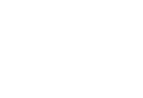

% Colors = [178,226,226
% 102,194,164
% 44,162,95
% 0,109,44]./255;
Colors = [
251,180,185
247,104,161
197,27,138
122,1,119]./255;


% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2*3};
FS = {'FontSize',10*3,15*3,18*3,21*3,30*3};
MS = {'MarkerSize',6,8,12,50*2,55*2};
LS = {'LineStyle','-','--','-.',':'};
LC = {'Color',Colors};



%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 1.1;
axt = 0.5;
axl = 1.0;
axr = 1.0;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;

%set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);

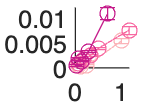

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 17);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["setwm_label", "lwr_lagQ", "upr_lagQ", "mean_lagQ", "wtd_meanp", "pvol", "tpeak", "tpeak_se", "NRF_peakht", "NRF_peakht_se", "width", "width_se", "rc", "rc_se", "rsum", "rsum_se", "nnz"];
opts.VariableTypes = ["string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "setwm_label", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "setwm_label", "EmptyFieldRule", "auto");

% Import the data
data = readtable("/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/UK_knots_antecedent/Rresults/1hr_simple_peakstats.txt", opts);



% Get unique lagQ ranges
lagQ_ranges = unique([data.lwr_lagQ, data.upr_lagQ], 'rows');

% Initialize figure
figure; hold on;

knot = NaN(5,size(lagQ_ranges,1));
knot_NRF_peakht=NaN(5,size(lagQ_ranges,1));
knot_NRF_peakht_se = NaN(5,size(lagQ_ranges,1));
% Loop over each lagQ range and plot the data
for i = 1:size(lagQ_ranges,1)
    % Get data for this lagQ range
    idx = data.lwr_lagQ == lagQ_ranges(i,1) & data.upr_lagQ == lagQ_ranges(i,2);
    lagQ_data = data(idx,:);
    
    % Remove rows where knot_NRF_peakht or knot_NRF_peakht_se are missing
    valid_idx = ~isnan(lagQ_data.NRF_peakht) & ~isnan(lagQ_data.NRF_peakht_se);
    lagQ_data = lagQ_data(valid_idx,:);
    
    % If no valid data, skip this iteration
    if isempty(lagQ_data)
        continue;
    end
    
    % Extract knot, knot_NRF_peakht, knot_NRF_peakht_se
    knot_ = lagQ_data.wtd_meanp;
    knot_NRF_peakht_ = lagQ_data.NRF_peakht;
    knot_NRF_peakht_se_ = lagQ_data.NRF_peakht_se;
    
    % Sort the data by knot for better visualization
    [knot(1:numel(knot_),i), sort_idx] = sort(knot_);
    knot_NRF_peakht(1:numel(knot_),i) = knot_NRF_peakht_(sort_idx);
    knot_NRF_peakht_se(1:numel(knot_),i) = knot_NRF_peakht_se_(sort_idx);
    
    % Plot with error bars
    errorbar(knot(:,i), knot_NRF_peakht(:,i), knot_NRF_peakht_se(:,i), '-o', 'Color', Colors(i,:), ...
        'DisplayName', sprintf('%.4f - %.4f mm/h', lagQ_ranges(i,1), lagQ_ranges(i,2)));
end

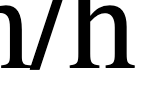

% Initialize figure
%set figure page
f1 = figure;
set(f1,'Units','Inches','Position',[0.7 12 fw fh]);
set(f1,'PaperPosition',[0 0 fw*2.2 fh*2.2],'PaperSize',[fw fh]);
set(f1,'Color','w','InvertHardcopy','off', 'MenuBar','none');
set(f1,'Resize','off','Toolbar','none');
ax = axes('Units','Inches','position',[axl axb axw axh]);
hold on
for i = 1:size(lagQ_ranges,1)
% Plot with error bars
    plot(knot(1:end,i), knot_NRF_peakht(1:end,i), '-', 'Color', Colors(i,:),LW{[1,5]},MS{[1,5]});
    legendText{i} = sprintf('%.2f - %.2f mm/h', round(100*lagQ_ranges(i,1))/100, round(100*lagQ_ranges(i,2))/100);

end
errorbar(knot(1:end,:), knot_NRF_peakht(1:end,:), knot_NRF_peakht_se(1:end,:),'.k','LineStyle', 'none',MS{[1,6]},...
         "MarkerEdgeColor","black",LW{[1,5]});
for i = 1:size(lagQ_ranges,1)
% Plot with error bars
    plot(knot(1:end,i), knot_NRF_peakht(1:end,i), '.', 'Color', Colors(i,:),MS{[1,5]});

end

set(gca, LW{[1,4]},TL{:},FS{[1,5]});
ax.YAxis.Exponent = -3;  % forces ×10⁻³ formatting

% Add labels, legend, and title
xlabel('Rainfall intensity [mm/h]',TX{:},FS{[1,5]},UN{[1,3]});
ylabel('Peak NRF [mm/h]',TX{:},FS{[1,5]},UN{[1,3]});
[lgd, hobj, ~, ~] = legend(legendText,TX{:},FS{[1,4]},'Location','northwest');
adjustLegendSize(lgd,hobj,1.05,1.00,10,1);

 % hl = findobj(hobj,'type','line');
 %  set(hl, 'LineWidth', 10);

title('');
hold off;

%Save figure
if printfig
  cd(workdirfig);
  % set printing options
  str       = {'NRF_runoff' };
  format    = '-dpng';
  resl      = '-r200';
  rend      = '-opengl';
  figname   = char(strcat(str(1)));
  print(f1,format,resl,rend,figname,'-loose');
end